clear 
clc

load ifk.mat

[m,n] = size(d);
a = 0; b = 1;

n = m;

sig  = 5e-5;

dx = (b-a)/m;
g = @(x,y) x*exp(-x*y);

x = [];
for j = 1:n
    x = [x  a + (dx/2) + (j-1)*dx]; %form x
end
y = x;

G = zeros(m,n);

for i = 1:m
    for j = 1:n
        G(i,j) = g(x(j),y(i)).*dx; %form G
    end
end

delta = m*(sig^2);

%zeroth order Tikhonov
[U,sm,X,V,W] = cgsvd(G,eye(n));

%regtools
[alpha0,rho,eta,reg_param] = l_curve(U,sm,d,'Tikh');

### N0.2 Use the discrepancy principle and the regularized discrepancy principle to find values for α in both first and second order Tikhonov regularization.

%form L1 and L2 matrices
L1 = zeros(n-2,n-1);
for i=2:n-1
    for j=1:n
        L1(1,1) = -1;
        L1(1,2) = 1;
        if (i==j)
            L1(i,j) = -1;
        elseif (j==i+1) 
            L1(i,j) =1;
        end
    end
end
L1

L1 =     -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0   

L2 = zeros(n-3,n-1);
for i=2:n-2
    for j=1:n
        L2(1,1) = 1;
        L2(1,2) = -2;
        L2(1,3) = 1;
        if (i==j)
            L2(i,j) = 1;
        elseif (j==i+1) 
            L2(i,j) = -2;
        elseif (j==i+2) 
            L2(i,j) = 1;
        end
    end
end

%m_alpha,L
m_al1 = @(alpha) inv(G'*G + (alpha^2).*(L1'*L1))*(G'*d);

m_al2 = @(alpha) inv(G'*G + (alpha^2).*(L2'*L2))*(G'*d);

### Using the discrepancy principle

%first order
options = optimset('Display','off');
f = @(alpha) norm(G*m_al1(alpha) - d,2)^2 - delta; %non linear function
alpha11 = fsolve(f,alpha0,options)

alpha11 = 2.5058e-05

%second order
f = @(alpha) norm(G*m_al2(alpha) - d,2)^2 - delta; %non linear function
alpha12 = fsolve(f,alpha0,options)

alpha12 = 2.5058e-05

### Using regularised discrepancy principle

%first order
p = rank(L1);
deltareg = m-n+p;
freg = @(alpha) (norm(G*m_al1(alpha) - d)^2)/(sig^2) + (alpha^2)*norm(L1*m_al1(alpha))^2 - deltareg;

alpha21 = fsolve(freg,alpha0,options)

alpha21 = 0.0025

%second order
p = rank(L2);
deltareg = m-n+p;
freg = @(alpha) (norm(G*m_al2(alpha) - d)^2)/(sig^2) + (alpha^2)*norm(L2*m_al2(alpha))^2 - deltareg;

alpha22 = fsolve(freg,alpha0,options)

alpha22 = 0.0148

### Comment on how they are similar or different, and the implications of the magnitude of these $\alpha$ in the optimization problem.

The discrepancy principle gives similar alpha values for both first and second order Tikhonov regularizations while the regularised discrepancy principle yields different values of alpha for both first and second order Tikhonov regularizations, the difference in these values of alpha is due to using different roughening matrices, the value of the standard deviation e.t.c. The magnitude of alpha values impact highly the shape of the curve for the model parameters.

### No.3 Plot model parameter estimates using first and second order Tikhonov regularization

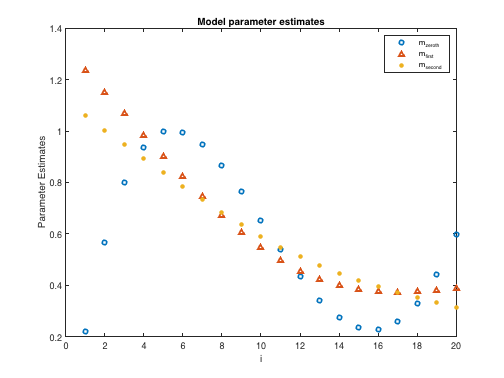

M = @(alpha,L) inv(G'*G + (alpha^2)*(L'*L))*G'*d;

%using the generalised discrepancy
alpha = [alpha0 alpha21  alpha22];

m0 = M(alpha(1),eye(n));
m21 = M(alpha(2),L2);
m22 = M(alpha(3),L2);

figure(1)
clf
plot(m0,'o','LineWidth',2,"MarkerSize",5); hold on
plot(m21,'^','LineWidth',2,"MarkerSize",5); 
plot(m22,'*','LineWidth',2,"MarkerSize",5); 
legend('m_{zeroth}','m_{first}','m_{second}')
xlabel('i'); ylabel('Parameter Estimates')
title('Model parameter estimates')

### Discuss the difference between the first and second order estimates, and how they relate to estimates from zeroth order Tikhonov regularization in the previous activity.

A seen from the graph above, the first and second order estimates overlap each at certain ranges: i<7, 7<=i<17, and i=>17, however they almost coincide at certain indicies: i=7 and 8, and this is due to the different roughening matrices used to geenrate the values of alpha which affect the nature of the model parameters. The shape of the curve from the zeroth Tikhonov regularization is very different from that of the first and second order, this is due to the value of alpha for the zeroth order being very small compared to those of  the first and second order and also the standard deviation used. Some of the second order points almost coincide with that of the zeroth order, and the alpha from the zeroth order acted as an intaial value for both first and second order, therefore, both depend on the value of the zeroth order.

### No.4 Plot the Picard ratios for first and second order Tikhonov regularization for one of the same values of α you used in 3.

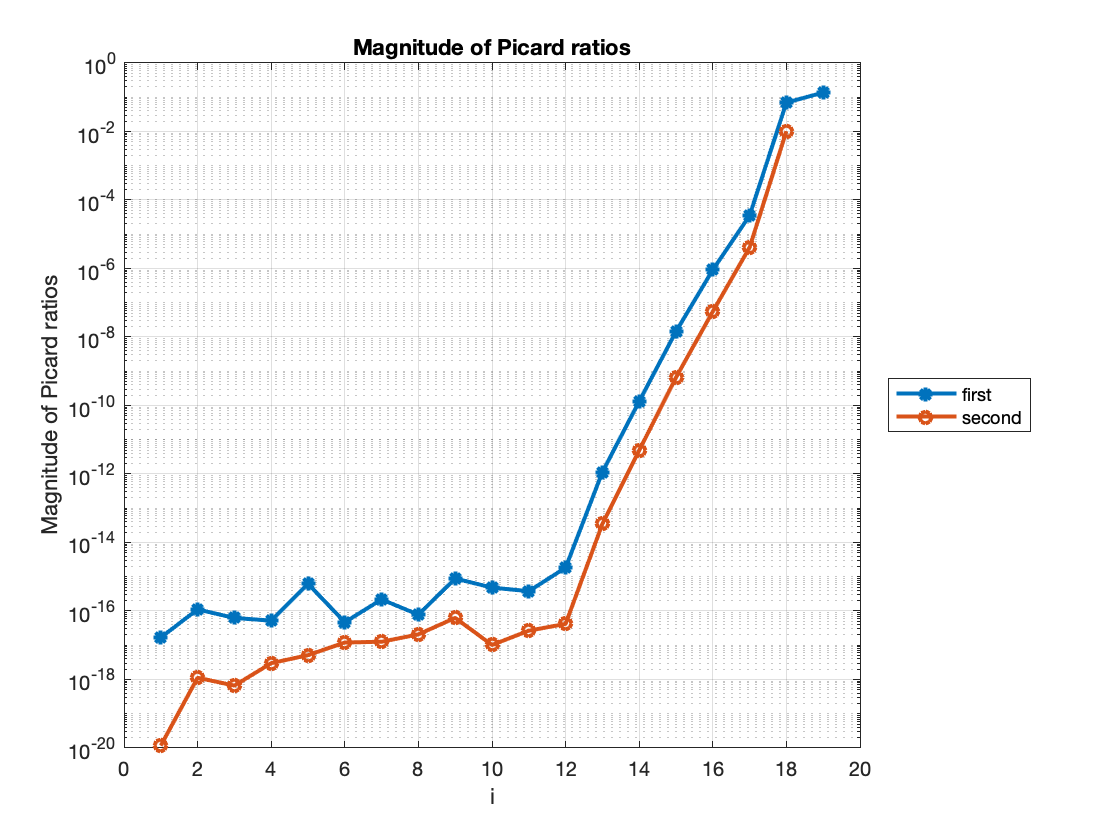

[U1,V1,X1,S1,M1] = gsvd(G,L1); Y1 = (inv(X1)'); 
[U2,V2,X2,S2,M2] = gsvd(G,L2); Y2 = (inv(X2)'); 

% generalized singular values of G and L
lam = @(S) sqrt(diag(S'*S));
mu = @(M) sqrt(diag(M'*M));

% filter parameters
fp1 = filtered(alpha(2),S1,M1,U1,d,m,lam,mu);
fp2 = filtered(alpha(3),S2,M2,U2,d,m,lam,mu);

figure(20)
semilogy(fp1,'-*',"LineWidth",2); hold on
semilogy(fp2,'-o',"LineWidth",2); grid on
legend('first','second','Location','eastoutside')
ylabel('Magnitude of Picard ratios'); xlabel('i');
title('Magnitude of Picard ratios');

### Identify where smaller singular values in the GSVD may cause the model parameter estimates to become unstable.

At i > 12

### No.5 Plot model parameter estimates using TGSVD, for both first and second order Tikhonov regularization, with 2 values for q in each case for which you get reasonable model parameter estimates.

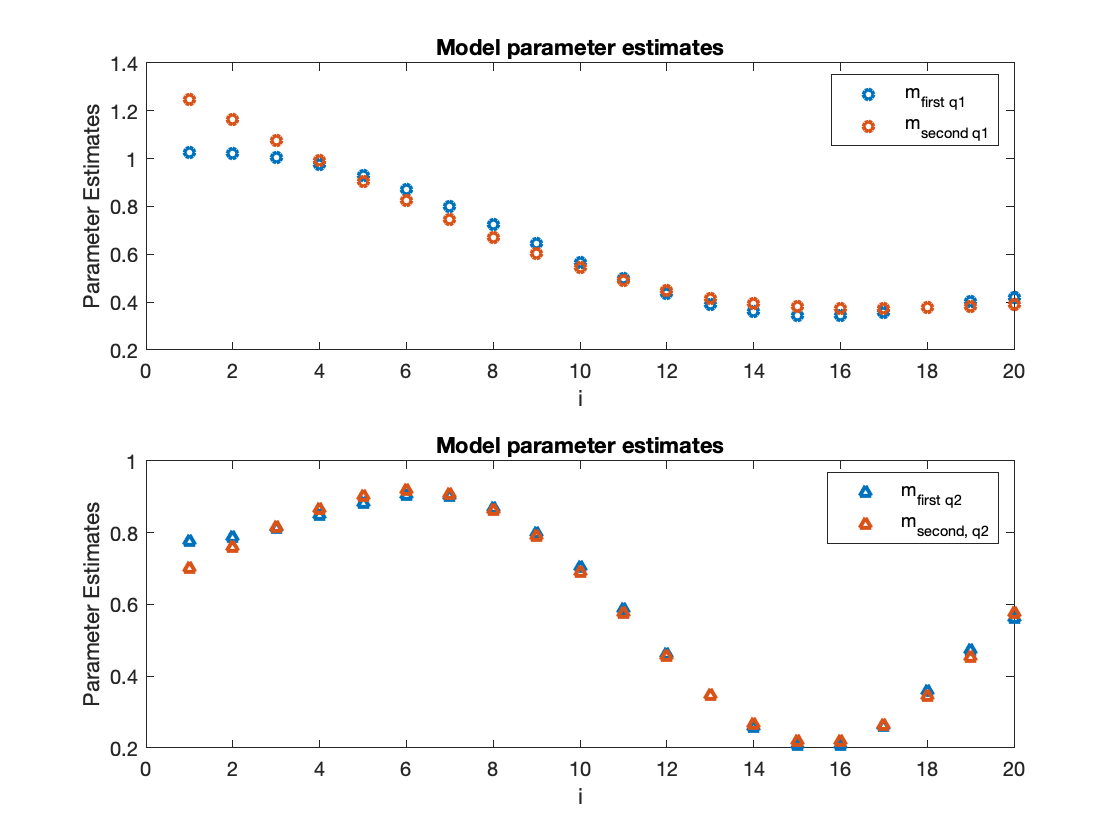

k = 0; %m=n
q1 = 3; q2 = 4;

Lam1 = lam(S1); Lam2 = lam(S2);

M1q1 = model_parameters(q1,U1,Lam1,Y1,k,d,n);
M1q2 = model_parameters(q2,U1,Lam1,Y1,k,d,n);
M2q1 = model_parameters(q1,U2,Lam2,Y2,k,d,n);
M2q2 = model_parameters(q2,U2,Lam2,Y2,k,d,n);

figure(4)
subplot(2,1,1)
plot(M1q1,'o','LineWidth',2,"MarkerSize",5); hold on
plot(M2q1,'o','LineWidth',2,"MarkerSize",5);
legend('m_{first q1}','m_{second q1}');
xlabel('i'); ylabel('Parameter Estimates')
title('Model parameter estimates')

subplot(2,1,2)
plot(M1q2,'^','LineWidth',2,"MarkerSize",5); hold on
plot(M2q2,'^','LineWidth',2,"MarkerSize",5);
legend('m_{first q2}','m_{second, q2}')
xlabel('i'); ylabel('Parameter Estimates')
title('Model parameter estimates')

### Discuss the accuracy and stability of these estimates.

The estimates obtained using a small vale of q are more accurate and stable compared to those with a larger value of q. We see unstability at i =7 for parameter estimates obtained using a larger value of q.

function [fp] = filtered(alpha,S,M,U,d,m,lam,mu)

    fp = [];
    gama = lam(S)./mu(M);
    lamb = lam(S);

    for i = 1:m
        fi = (gama(i)^2)/(gama(i)^2 + alpha^2);
        fp = [fp abs(fi.*(U(:,i)'*d)./lamb(i))];
    end
end

function [M] = model_parameters(q,U,Lam,Y,k,d,n)
    M = 0;
    for i = n-q+1:n
        M = M + (U(:,i-k)'*d)/(Lam(i))*Y(:,i);
    end
end
